# **SSM-based ROM of a FE model of a Tribomechadynamics benchmark problem**

In this example, we construct a reduced model for the dynamics of a finite element model of a Tribomechadynamics benchmark problem [1]. Due to excessive memory requirements of the full state-space free-decay data, the data has been first projected onto the first 100 modes of the system. Two required data files, xData.mat and V1.mat, should be downloaded from [link to supplementary files](https://polybox.ethz.ch/index.php/s/3FfFc4pjHsHDdTW).

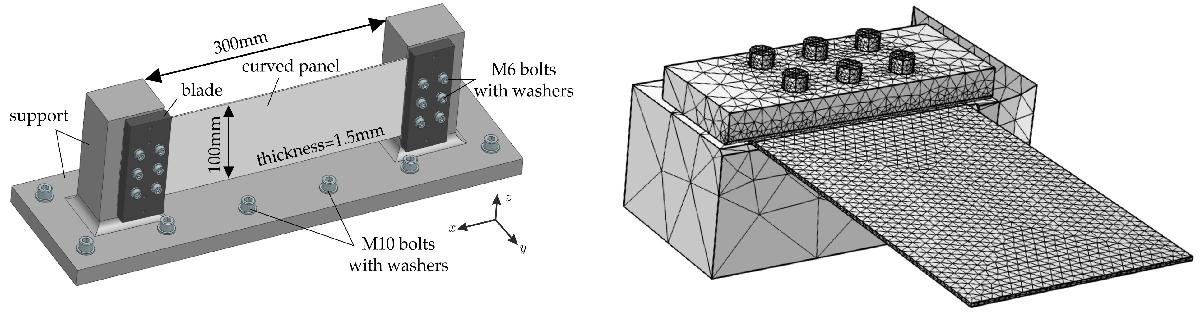

[[1] Morsy, Xu, Tiso & Haller, Data-Driven reduction of the finite-element model of a Tribomechadynamics benchmark problem, Nonlin. Dyn. [2025]](https://link.springer.com/article/10.1007/s11071-025-11378-8)

## Load data

First, we load the compressed data. The data consists of four free-decay trajectories. We use three trajectories for training and leave one out for testing. 

clear all; close all; clc
load('xData.mat') % the compressed four free-decay trajectories
load ('xData3DOFs.mat') % the time response of the 3 DOFs shown below in the figure

## Preliminary data analysis

We analyze the frequency content of the first bending trajectory. Specifically, we plot the spectrogram of the out-of-plane displacements of one of the corner nodes shown in the figure below. In addition to the higher harmonics of bending mode, we also notice the presence of the second, torsional mode of the system. We conclude that the structure features an internal resonance. Therefore, we seek a four-dimensional SSM.

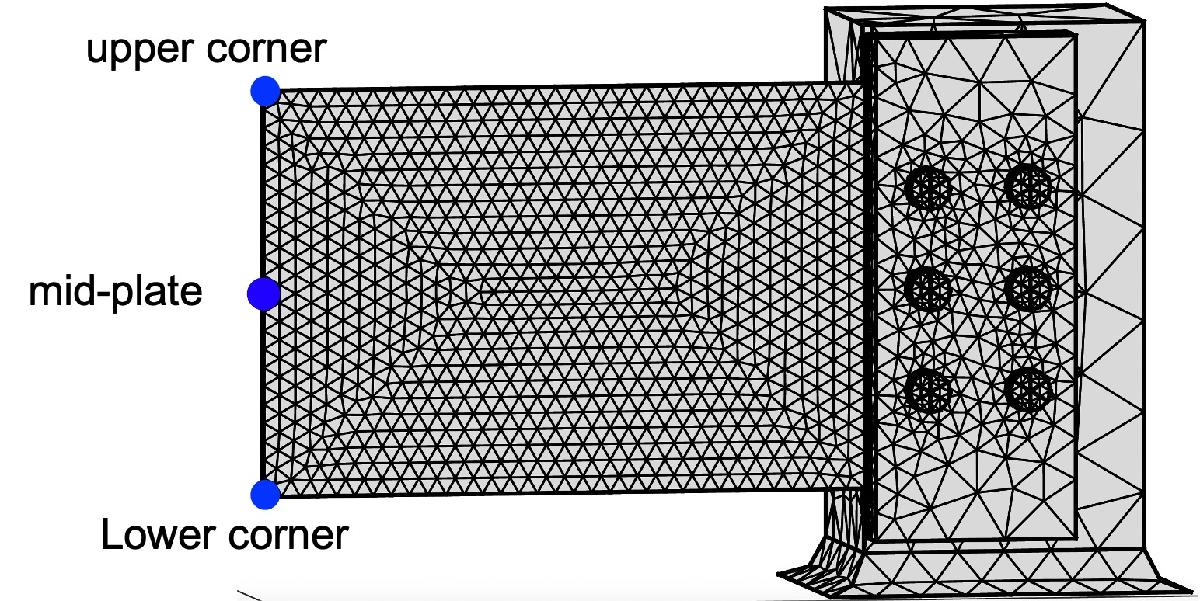

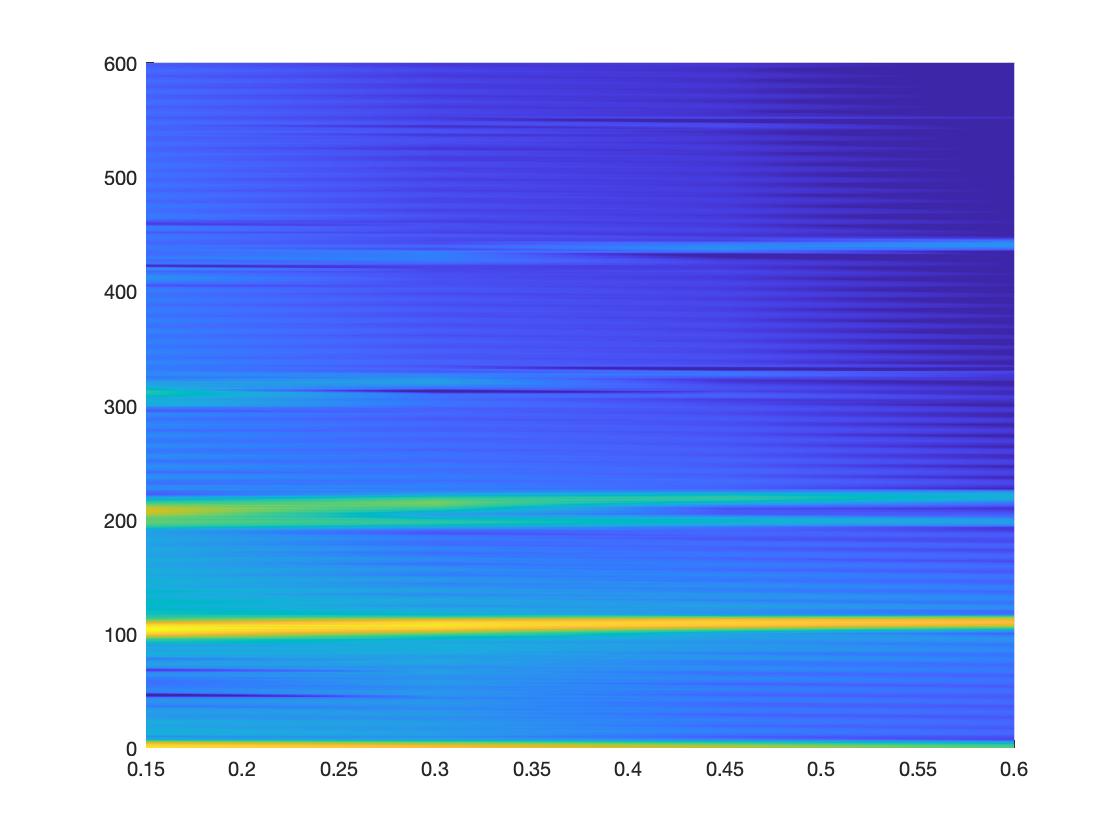

dof = 'lower_corner'; %choose dof of interest. Possibilities: 'midplate' 'lower_corner','upper_corner' 

switch dof
    case 'lower_corner'
        idx_coord= 1; 
    case 'midplate'
        idx_coord= 2;
    case 'upper_corner'
        idx_coord= 3;
end


t = xData3DOFs{1,1}; %time [s]
x = xData3DOFs{1,2}(idx_coord,:); %displacements [mm]
% plot spectrogram
Nwin = round(length(t)/5);
[stfourier, frequencies, times] = spectrogram(x, Nwin, round(Nwin*0.5), [], 1e4);
powerdensity = abs(stfourier);
surf(times, frequencies, powerdensity)
set(gca,'ColorScale','log')
xlim([min(times), 0.6]) 
ylim([0,600])
view(2)
shading interp

## Learn geometry (fastSSM)

Now, we seek to learn the geometry of the ROM. We first approximate the tangent space at the fixed point using SVD. Subsequently, we use a polynomial model to learn a 4-dim manifold.

mfddim = 4; % input manifold dimension
mfdorder = 5; % input polynomial order
indTrain = 1:3; % input indices of trajectories used for training
indTest = 4; % input index of trajectory used for testing

% learn manifold
t = horzcat(xData{:,1}); Y = horzcat(xData{:,2});
[u,s,v] = svds(Y, mfddim); V = max(abs(v'),[],2).'.*u*s;


iMmap = @(y) V\y; 
Xi = iMmap(Y); 
M = Y/phi(Xi, 1:mfdorder);
Mmap = @(xi) M*phi(xi, 1:mfdorder);
IMInfo = struct();  IMInfo.parametrization.map = Mmap;
IMInfo.parametrization.dimension = mfddim;  IMInfo.chart.map = iMmap;

% compute fitting error
etaDataTrain = projectTrajectories(IMInfo, xData(indTrain,:));
normedTrajDist = computeTrajectoryErrors(liftTrajectories(IMInfo,etaDataTrain), xData(indTrain,:));
staticNMTE = mean(normedTrajDist(1))*100

staticNMTE = 0.1533

## Learn dynamics (SSMLearn)

Next, we learn the reduced dynamics. The best fit we obtained has been saved as `RDInfo.mat`. We give examples of parameter assignments to the function `IMDynamicsFlow` in commented lines.

ROMOrder =	5; %input rom order

etaData = projectTrajectories(IMInfo, xData); %project the dynamics onto V

load RDInfoO5NF.mat % we obtained this fit from the next commented line
% RDInfo = IMDynamicsFlow(etaData(indTrain,:), ...
%     'R_PolyOrd', ROMOrder, 'style', 'normalform', 'MaxIter',100e3, 'IC_nf',2,...
%     'n_folds',0, 'l_vals',1,'rescale', 2, 'nf_style', 'actual eigs','tol_nf',3e1, 'MaxFunctionEvaluations', 10e4);

% Another example of parameter assignments to learn the dynamics
% RDInfo = IMDynamicsFlow(etaData(indTrain,:), ...
%     'R_PolyOrd', ROMOrder, 'style', 'modal', 'l_vals',1);

frequenciesHz = imag(RDInfo.eigenvaluesLinPartFlow(1:2))/2/pi;
% integrate the reduced model
[yRec, etaRec,zRec, ~] = advect(IMInfo, RDInfo, xData); 
% compute errors
[normedTrajDist,ampError] = computeTrajectoryErrors(etaRec(indTrain,:), etaData(indTrain,:));
NMTE = mean(normedTrajDist)*100

NMTE = 7.0716

## Plot reduced trajectories

Here we plot the reconstructions and predictions of free-decay trajectories in reduced coordinates. `Indplot `1,2,3 refer to training trajectories 1,2,3. Indplot 4 refers to the test trajectory.

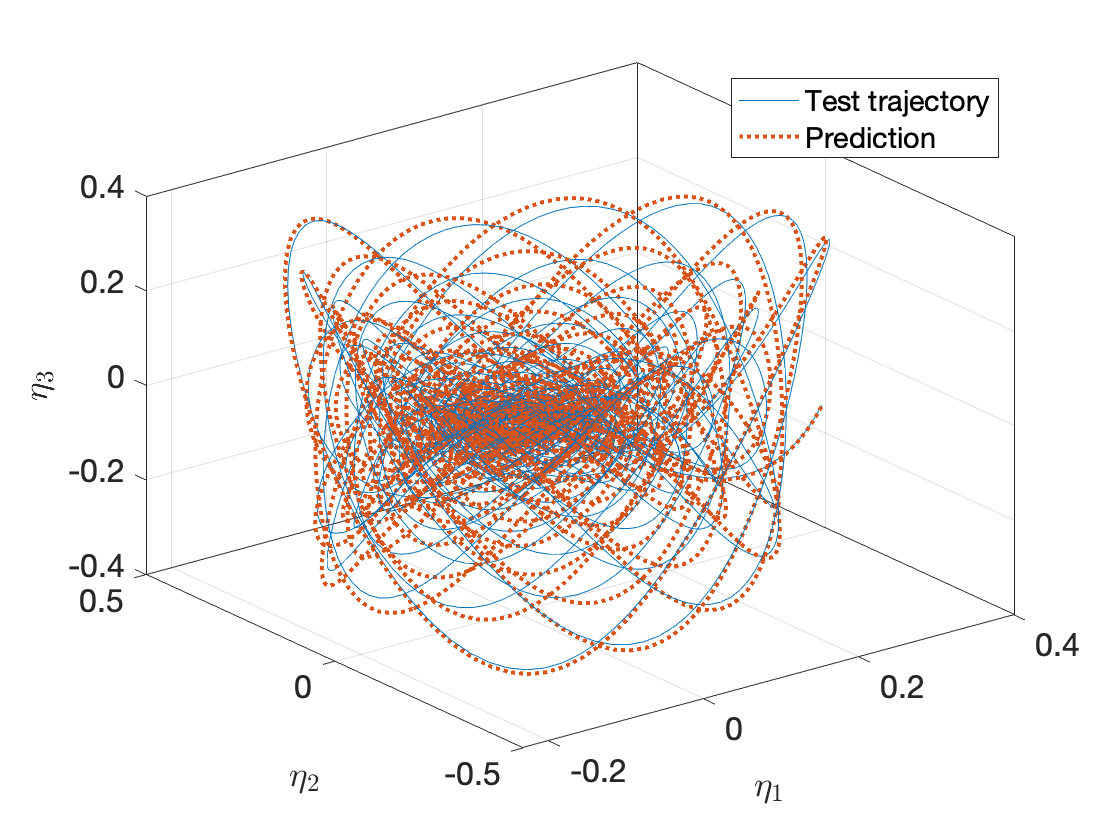

indplot = 4;
plotReducedCoordinates(etaData(indplot,:),etaRec(indplot,:),[1 2 3]); 
legend({'Test trajectory', 'Prediction'})
view(3)

## Plot free decay of chosen physical dof

Here we map the free-decay results to full state space. 

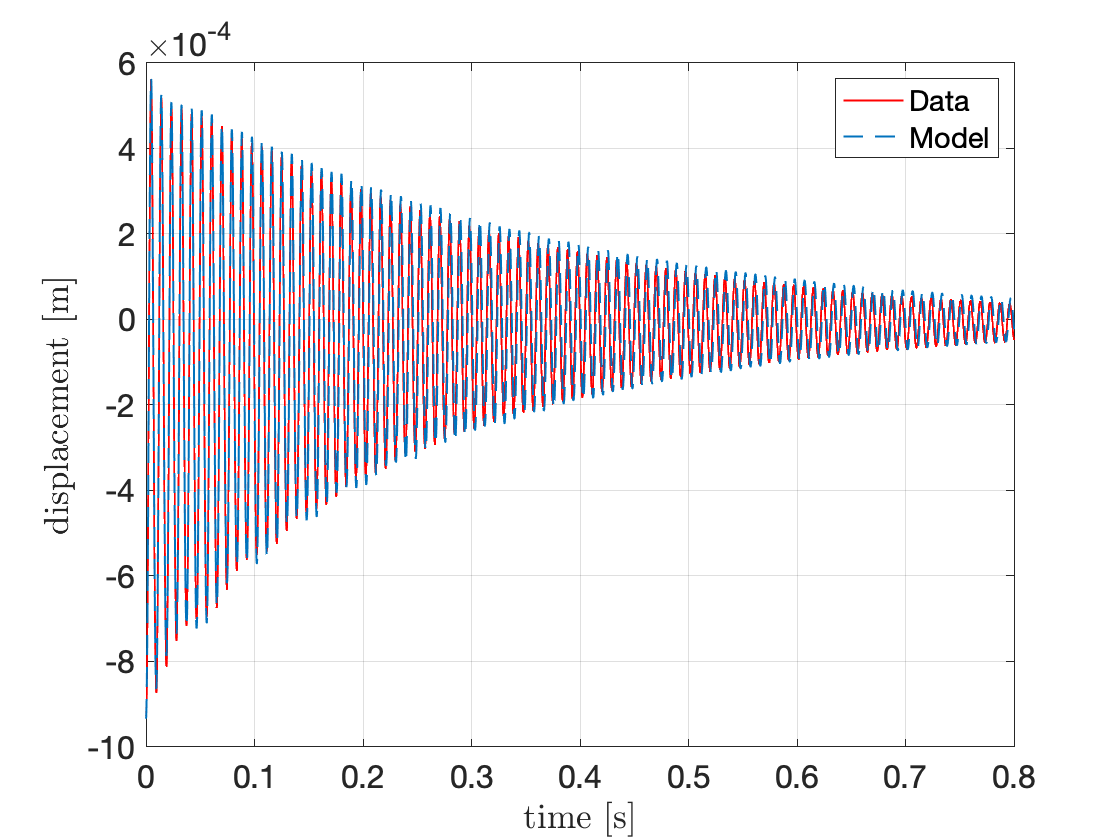

% Choose the DOF and trajectory of interest 
dof = 'midplate'; %options: 'midplate', 'lower_corner','upper_corner' 
trajectory = 'mix_test'; % options:  'bending_train', 'torsion_train', 'mix_train', 'mix_test'

switch dof
    case 'lower_corner'
        idx_coord= 1; 
    case 'midplate'
        idx_coord= 2;
    case 'upper_corner'
        idx_coord= 3;
end

switch trajectory
    case 'bending_train'
        iTraj = 1;
    case 'torsion_train'
        iTraj = 2;
    case 'mix_train'
        iTraj = 3;
    case 'mix_test'
        iTraj = 4;
end

coords = [138691,156981,163711]; 
% load the matrix whose columns feature the first 100 modes of the system.
load('V1.mat') 
for iTraj = 1:size(xData,1)
    yPhysical{iTraj,1} = xData{iTraj,1};
    yPhysical{iTraj,2} = V1(coords,:)*yRec{iTraj,2};
end


customFigure();
plot(xData3DOFs{iTraj,1}(1,:), xData3DOFs{iTraj,2}(idx_coord,:), '-', 'Color', 'r', 'LineWidth', 0.5, 'DisplayName', 'Data','LineWidth',1);
hold on
plot(yPhysical{iTraj,1}(1,:), yPhysical{iTraj,2}(idx_coord,:), '--', 'Color', [0 0.4470 0.7410], 'LineWidth', 0.5, 'DisplayName', 'Model','LineWidth',1);
xlabel('time [s]', 'Interpreter', 'latex');
ylabel('displacement [m]','Interpreter','latex');
legend

## ROM forced Response

Having validated the model based on predictions of free-decay, we now seek to predict the response at the midplate DOF under periodic base excitation. 

forcingAmps = [2,4]; %input base acceleration [m/s^2]

load ForceVector.mat
outdofs = 1:size(Y,1);
amplitudeFunction = @(x) x(outdofs,:); 
IMInfo.parametrization.tangentSpaceAtOrigin = V;
nSweeps = length(Force);
Force = [zeros(nSweeps,1);Force];
projForce = pinv(V1)*Force; 
fRed = RDInfo.inverseTransformation.lintransf*IMInfo.chart.map(projForce);
fRed = [fRed(1) ,fRed(2)];
omegaSpan = [0.9 1.1]*imag(RDInfo.eigenvaluesLinPartFlow(1)); 
forcingAmps = forcingAmps.*transpose(fRed); 
[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo,'nForcingFrequencies',1);

Forced SSM reduced-order model assumes external forcing only along the tangent (modal) subspace at the origin. 


% continuationFRCpo_vecOutput is a simple modification of continuationFRCpo to
% allow for vector outputs
FRCDataCOCO = continuationFRCpo_vecOutput(IMInfoF,RDInfoF,forcingAmps/2,omegaSpan,amplitudeFunction,outdofs);

Frequency sweep for the set of forcing values number 1 ...

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.22e-04  4.43e-02    0.0    0.0    0.0
   1   1  1.00e+00  1.26e-04  3.41e-11  4.44e-02    0.0    0.0    0.0
   2   1  1.00e+00  1.67e-09  1.29e-17  4.44e-02    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE     po.period            T
    0  00:00:00   4.4362e-02      1  EP      1.0058e-02   1.0058e-02
   10  00:00:01   3.7169e-01      2          9.1701e-03   9.1701e-03
   11  00:00:01   3.7461e-01      3  SN      9.1700e-03   9.1700e-03
   11  00:00:01   3.7462e-01      4  FP      9.1700e-03   9.1700e-03
   20  00:00:02   5.6820e-01      5          9.1935e-03   9.1935e-03
   30  00:00:02   7.6352e-01      6          9.2138e-03   9.2138e-03
   31  00:00:02   7.6827e-01      7  FP      9.2140e-03   9.2140e-03
   31  00:00:02   7.6827e-01      8  

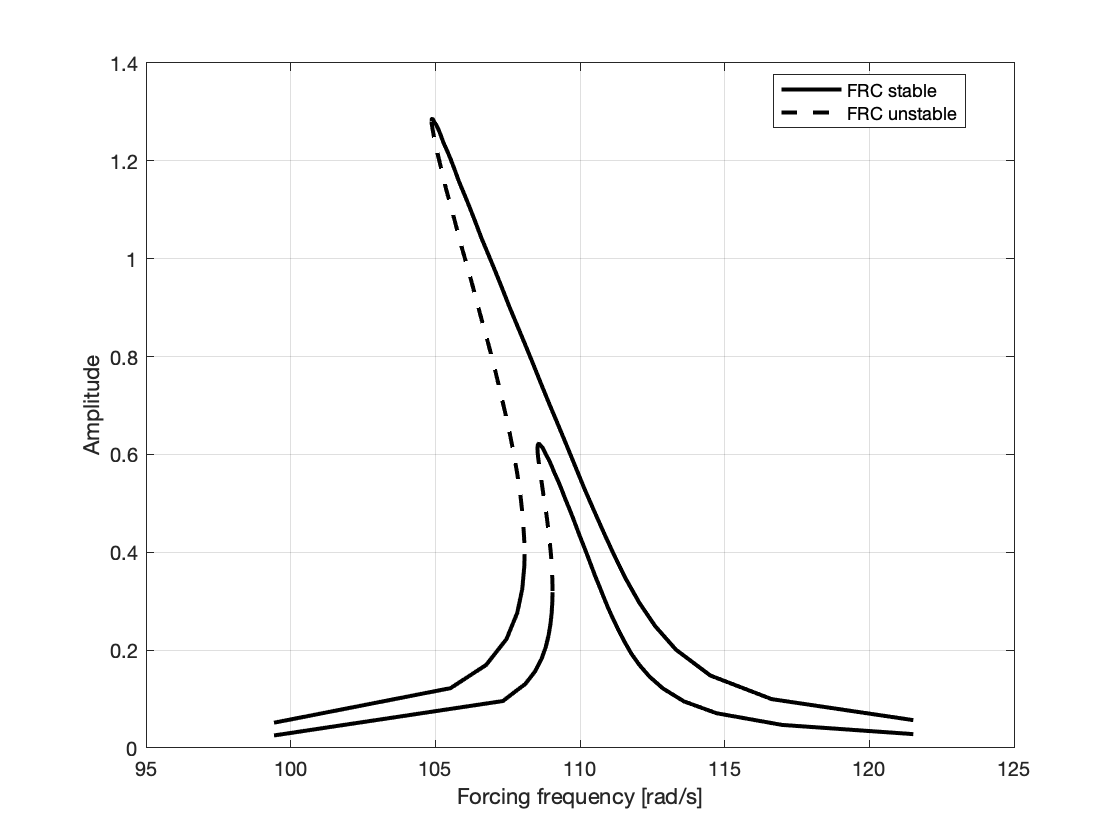

nSweeps = numel(fieldnames(FRCDataCOCO));
for iSweep = 1:nSweeps
    fieldName = ['F', num2str(iSweep)];   
    FRCDataCOCO.(fieldName).Amp = V1(coords(2),:) *FRCDataCOCO.(fieldName).Amp*1e3;
    FRCDataCOCO.(fieldName).Freq = FRCDataCOCO.(fieldName).Freq/2/pi;
end
close all
plotFRC(FRCDataCOCO)

## Compare with forced responses

For comparison, we also plot the periodic responses obtained by time integration of the full model at a few frequency and amplitude samples.

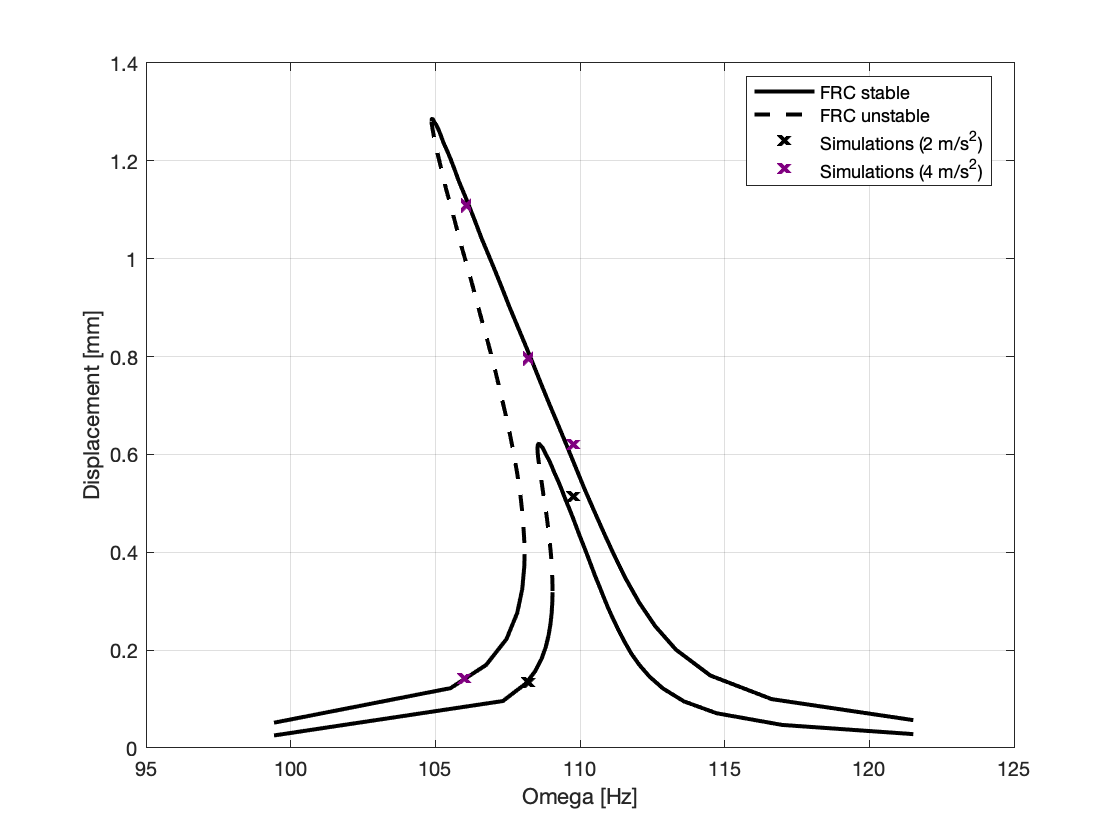

hold on
load comsolPOs.mat
scatter(comsolPOs{1,1},comsolPOs{1,2},'x','MarkerEdgeColor','k','LineWidth',2,'SizeData',40,'DisplayName','Simulations (2 m/s^{2})')
scatter(comsolPOs{2,1},comsolPOs{2,2},'x','MarkerEdgeColor',[0.5 0 0.5],'LineWidth',2,'SizeData',40,'DisplayName','Simulations (4 m/s^{2})')
xlabel('Omega [Hz]')
ylabel('Displacement [mm]')